%EXAMPLE IMPORT AND PLOT
record_name = '3000063';
number = '0007';

folder = record_name(1:2);

data = importdata("physionet.org/textdata/"+record_name+"_"+number+".txt")

data = 	1.0e+03 *

         0    0.0445    0.0006
    0.0000    0.0479    0.0006
    0.0000    0.0507    0.0006
    0.0000    0.0536    0.0006
    0.0000    0.0559    0.0007
    0.0000    0.0576    0.0007
    0.0000    0.0593    0.0007
    0.0001    0.0604    0.0007
    0.0001    0.0610    0.0007
    0.0001    0.0616    0.0007


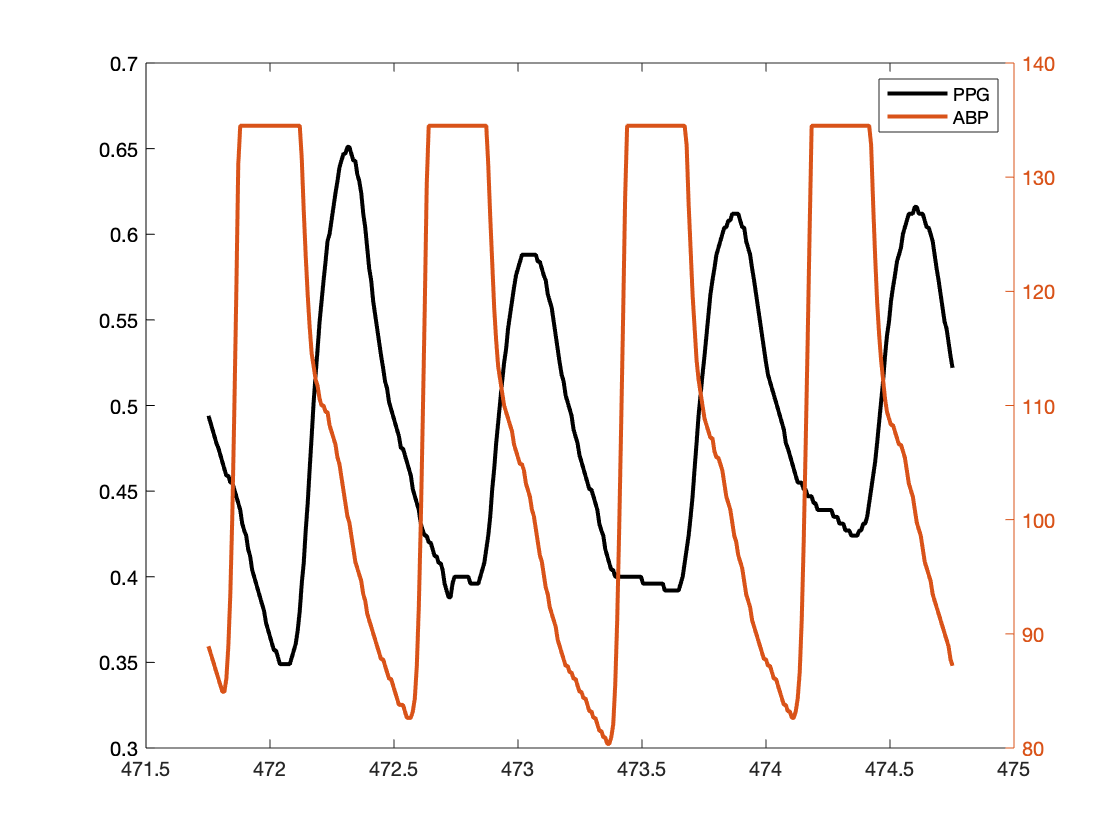


signal = data(:,2:3);
tm = data(:,1);

start_disp = round(length(tm)/4);
end_disp = start_disp+3*Fs;
clf
 plot(tm(start_disp:end_disp), signal(start_disp:end_disp,2), 'LineWidth', 2)
hold on
yyaxis right
plot(tm(start_disp:end_disp,1), signal(start_disp:end_disp,1), 'LineWidth',2)
legend("PPG", "ABP")

%FILTERING